## Exercise 1

setup

clear
addpath("frffit"); addpath("Assignments")

f1 = 40;        %[Hz] frequency zeros
f2 = 40;        %[Hz] frequency poles
B1 = 0.1;      %damping zeros
B2 = 1;         %damping poles
num = [1/(2*pi*f1)^2 (2*B1)/(2*pi*f1) 1]

num =     0.0000    0.0008    1.0000


den = [1/(2*pi*f2)^2 (2*B2)/(2*pi*f2) 1]

den =     0.0000    0.0080    1.0000


b) Analysis time domain

out = sim("assignment_two.slx") %running the model

out =   Simulink.SimulationOutput:

                  input: [1x1 timeseries] 
                 output: [1x1 timeseries] 
                   tout: [30001x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


figure()
hold on
x = out.input

  timeseries

  Common Properties:
            Name: ''
            Time: [30001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [30001x1 double]
        DataInfo: 

y = out.output

  timeseries

  Common Properties:
            Name: ''
            Time: [30001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [30001x1 double]
        DataInfo: 

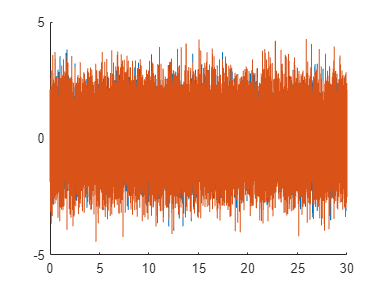

plot(x.Time,x.Data)
plot(y.Time,y.Data)

c) Analysis frequency domain

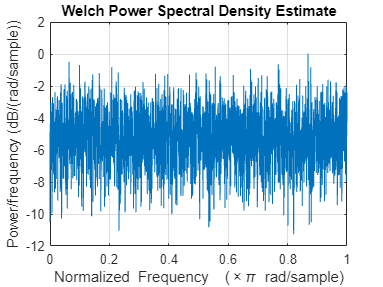

%spectral power analysis
figure()
pwelch(x.Data)

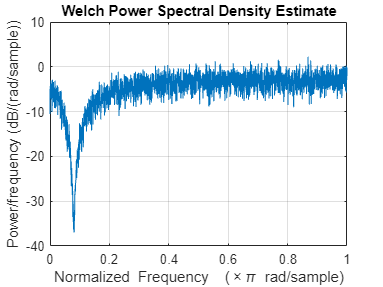

figure()
pwelch(y.Data)

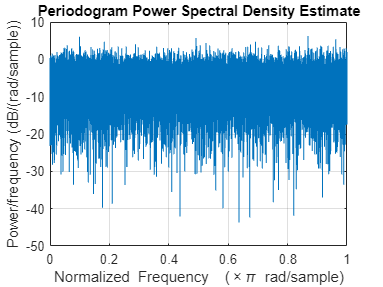


%periodogram
figure()
periodogram(x.Data)

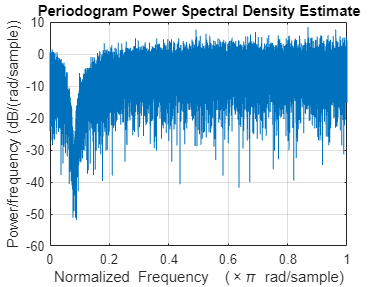

figure()
periodogram(y.Data)


%fft
F_in = fft(x.Data)

F_in = 1.0e+02 *

  -0.3033 + 0.0000i
  -0.7637 + 1.2966i
   0.0299 - 0.2123i
   0.6914 + 0.4372i
   2.0776 - 0.6094i
   1.6132 - 1.0148i
  -1.9042 + 0.5529i
   0.2445 + 2.8052i
   1.8620 + 1.7957i
   0.1636 + 0.0303i


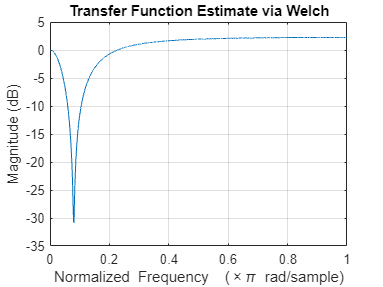


%bode plots
figure()
tfestimate(x.Data,y.Data)

d) FRF 

X = periodogram(x.Data)

X =     0.0049
    0.2560
    0.0252
    0.1703
    0.3128
    0.0166
    1.1045
    0.5228
    0.2335
    0.6739


Y = periodogram(y.Data)

Y =     0.0040
    0.2546
    0.0270
    0.1774
    0.3158
    0.0179
    1.1170
    0.5311
    0.2249
    0.6738


Fs = 1000

Fs = 1000

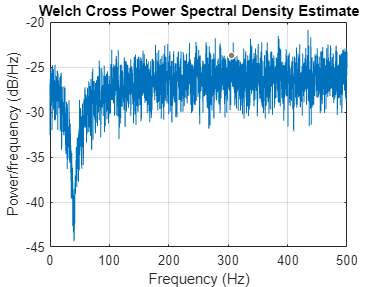

cpsd(x.Data,y.Data,[],[],[],Fs)

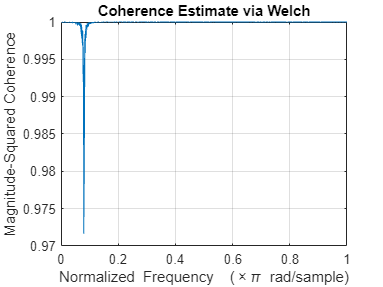



mscohere(x.Data,y.Data)